syms Kp Kv K t s Ks
expr1 = K/((t*s)+1);
expr2 = expr1/(1+(expr1*Kv));
expr3 = expr2*Kp*(1/s);
expr4 = expr3/(1+expr3);
collect(expr4,s)

$$ans = \frac{K\,\mathrm{Kp}}{t\,s^{2}+\left(K\,\mathrm{Kv}+1\right)\,s+K\,\mathrm{Kp}}$$

expr11 = Ks*(1/(s+1))*(1/(s+1));
expr12 = expr11/(1+expr11);
collect(expr12,s);
s = tf('s');
stepinfo(tf([1],[1 1 3]));
31/4;

ans =                       7.75


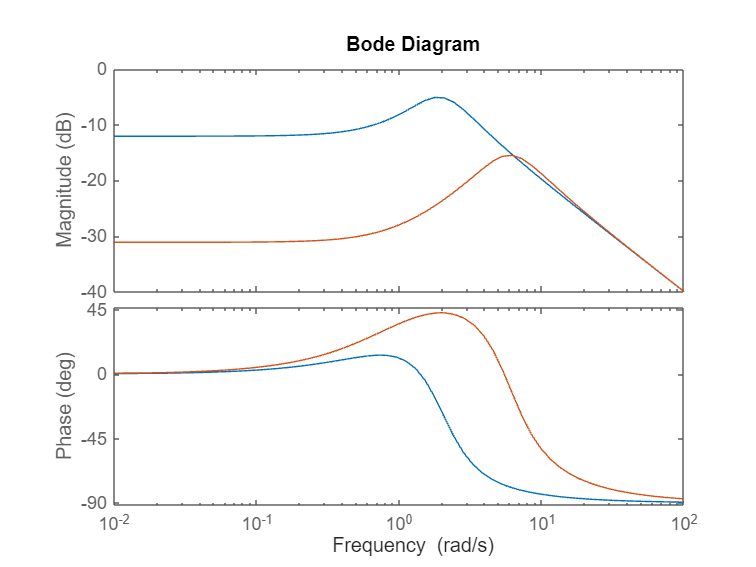

close all;
clear;
syms Kp Kv K t Ks
s = tf('s');
Ks = 3;
Kc = 7.75;
serie = (s+1)/(s^2+2*s+1+Ks);
f = (s+1)/(s+5);
g = 4/(s+5);
casc= (f*(1/(s+1)))/(1+((1/(s+1)*Kc*g)));
bode(serie,casc)